% load data
load('VarsToPlot.mat')

whos

  Name                      Size                Bytes  Class                                    Attributes

  AllNames                551x1                 31370  string                                             
  AllTreatments           551x1                 29850  string                                             
  Combined                  2x29                 3308  string                                             
  CorrectScore              7x1                    56  double                                             
  ExpGroups                 1x2                   228  cell                                               
  GroupColors               1x2                   256  cell                                               
  Ind1                     29x1                   232  double                                             
  Ind2                    551x1                  4408  double                                             
  IndThisGroup              1x1     

% find out variables
disp(SBS.Properties.VariableNames)

  Columns 1 through 3
    {'Subject'}    {'Group'}    {'Date'}
  Columns 4 through 6
    {'Session'}    {'Task'}    {'Type'}
  Columns 7 through 9
    {'nBlock'}    {'nTrial'}    {'Dark'}
  Columns 10 through 12
    {'Cor'}    {'Pre'}    {'Late'}
  Columns 13 through 15
    {'Cor_S'}    {'Cor_M'}    {'Cor_L'}
  Columns 16 through 18
    {'Pre_S'}    {'Pre_M'}    {'Pre_L'}
  Columns 19 through 21
    {'Late_S'}    {'Late_M'}    {'Late_L'}
  Columns 22 through 24
    {'maxFP'}    {'t2mFP'}    {'minRW'}
  Columns 25 through 27
    {'t2mRW'}    {'t2c'}    {'t2cInv'}
  Columns 28 through 30
    {'HT'}    {'RT'}    {'MT'}


disp(TBT.Properties.VariableNames)

  Columns 1 through 3
    {'Subject'}    {'Date'}    {'Session'}
  Columns 4 through 6
    {'Group'}    {'StartTime'}    {'Task'}
  Columns 7 through 9
    {'iTrial'}    {'BlockNum'}    {'TrialNum'}
  Columns 10 through 12
    {'TrialType'}    {'TimeElapsed'}    {'FP'}
  Columns 13 through 15
    {'RW'}    {'DarkTry'}    {'ConfuseNum'}
  Columns 16 through 19
    {'Outcome'}    {'HT'}    {'RT'}    {'MT'}


% find out rats
AllNames        =       SBS.Subject;
AllTreatments   =       SBS.Group;
[UnqNames, Ind1, Ind2]     =       unique(AllNames);
UnqGroups = AllTreatments(Ind1);
Combined = [UnqNames UnqGroups]';

fprintf('%s; %s\n', Combined);

Aqua; Lesion
Bertrand; Sham
Cash; Lesion
Denisty; Lesion
Engel; Sham
Fran; Lesion
Ginsburg; Sham
Hsiao-hsien; Sham
Huppert; Sham
Ingmar; Lesion
Iver; Lesion
Jupiter; Lesion
Kepler; Sham
Kieslowski; Sham
Leonard; Lesion
Matias; Sham
Nicola; Lesion
ONeal; Sham
Panini; Sham
Quesadilla; Lesion
Risotto; Sham
Sushi; Lesion
Troels; Lesion
Ulysess; Sham
Vivaldi; Lesion
Walter; Sham
Xaiver; Lesion
Yvan; Sham
Zeno; Sham


% find out behavioral session types
[UnqTasks]  = unique(SBS.Task);
fprintf('%s\n', UnqTasks)

3FPs
Wait1
Wait2


% Test: get sessions of Ingmar, Wait 1
% sess_pre = unique(SBS.Session(cellfun(@(x) ~isempty(x),strfind(SBS.Group,'Pre'))));
for k = 1:length(UnqTasks)
    for i =1:length(UnqNames)
        disp([UnqNames{i} '/' UnqGroups{i} '/' UnqTasks{k}])
        disp(transpose(SBS.Session(strcmp(SBS.Task, UnqTasks{k}) & strcmp(SBS.Subject, UnqNames{i}))))
    end;
end;

Aqua/Lesion/3FPs


    13    14    15    16    17    18    19


Bertrand/Sham/3FPs


    13    14    15    16    17    18    19


Cash/Lesion/3FPs


    13    14    15    16    17    18    19


Denisty/Lesion/3FPs


    13    14    15    16    17    18    19


Engel/Sham/3FPs


    13    14    15    16    17    18    19


Fran/Lesion/3FPs


    13    14    15    16    17    18    19


Ginsburg/Sham/3FPs


    13    14    15    16    17    18    19


Hsiao-hsien/Sham/3FPs


    13    14    15    16    17    18    19


Huppert/Sham/3FPs


    13    14    15    16    17    18    19


Ingmar/Lesion/3FPs


    13    14    15    16    17    18    19


Iver/Lesion/3FPs


    13    14    15    16    17    18    19


Jupiter/Lesion/3FPs


    13    14    15    16    17    18    19


Kepler/Sham/3FPs


    13    14    15    16    17    18    19


Kieslowski/Sham/3FPs


    13    14    15    16    17    18    19


Leonard/Lesion/3FPs


    13    14    15    16    17    18    19


Matias/Sham/3FPs


    13    14    15    16    17    18    19


Nicola/Lesion/3FPs


    13    14    15    16    17    18    19


ONeal/Sham/3FPs


    13    14    15    16    17    18    19


Panini/Sham/3FPs


    13    14    15    16    17    18    19


Quesadilla/Lesion/3FPs


    13    14    15    16    17    18    19


Risotto/Sham/3FPs


    13    14    15    16    17    18    19


Sushi/Lesion/3FPs


    13    14    15    16    17    18    19


Troels/Lesion/3FPs


    13    14    15    16    17    18    19


Ulysess/Sham/3FPs


    13    14    15    16    17    18    19


Vivaldi/Lesion/3FPs


    13    14    15    16    17    18    19


Walter/Sham/3FPs


    13    14    15    16    17    18    19


Xaiver/Lesion/3FPs


    13    14    15    16    17    18    19


Yvan/Sham/3FPs


    13    14    15    16    17    18    19


Zeno/Sham/3FPs


    13    14    15    16    17    18    19


Aqua/Lesion/Wait1


     1     2     3     4     5


Bertrand/Sham/Wait1


     1     2     3     4     5


Cash/Lesion/Wait1


     1     2     3     4     5


Denisty/Lesion/Wait1


     1     2     3     4     5


Engel/Sham/Wait1


     1     2     3     4     5


Fran/Lesion/Wait1


     1     2     3     4     5


Ginsburg/Sham/Wait1


     1     2     3     4     5


Hsiao-hsien/Sham/Wait1


     1     2     3     4     5


Huppert/Sham/Wait1


     1     2     3     4     5


Ingmar/Lesion/Wait1


     1     2     3     4     5


Iver/Lesion/Wait1


     1     2     3     4     5


Jupiter/Lesion/Wait1


     1     2     3     4     5


Kepler/Sham/Wait1


     1     2     3     4     5


Kieslowski/Sham/Wait1


     1     2     3     4     5


Leonard/Lesion/Wait1


     1     2     3     4     5


Matias/Sham/Wait1


     1     2     3     4     5


Nicola/Lesion/Wait1


     1     2     3     4     5


ONeal/Sham/Wait1


     1     2     3     4     5


Panini/Sham/Wait1


     1     2     3     4     5


Quesadilla/Lesion/Wait1


     1     2     3     4     5


Risotto/Sham/Wait1


     1     2     3     4     5


Sushi/Lesion/Wait1


     1     2     3     4     5


Troels/Lesion/Wait1


     1     2     3     4     5


Ulysess/Sham/Wait1


     1     2     3     4     5


Vivaldi/Lesion/Wait1


     1     2     3     4     5


Walter/Sham/Wait1


     1     2     3     4     5


Xaiver/Lesion/Wait1


     1     2     3     4     5


Yvan/Sham/Wait1


     1     2     3     4     5


Zeno/Sham/Wait1


     1     2     3     4     5


Aqua/Lesion/Wait2


     6     7     8     9    10    11    12


Bertrand/Sham/Wait2


     6     7     8     9    10    11    12


Cash/Lesion/Wait2


     6     7     8     9    10    11    12


Denisty/Lesion/Wait2


     6     7     8     9    10    11    12


Engel/Sham/Wait2


     6     7     8     9    10    11    12


Fran/Lesion/Wait2


     6     7     8     9    10    11    12


Ginsburg/Sham/Wait2


     6     7     8     9    10    11    12


Hsiao-hsien/Sham/Wait2


     6     7     8     9    10    11    12


Huppert/Sham/Wait2


     6     7     8     9    10    11    12


Ingmar/Lesion/Wait2


     6     7     8     9    10    11    12


Iver/Lesion/Wait2


     6     7     8     9    10    11    12


Jupiter/Lesion/Wait2


     6     7     8     9    10    11    12


Kepler/Sham/Wait2


     6     7     8     9    10    11    12


Kieslowski/Sham/Wait2


     6     7     8     9    10    11    12


Leonard/Lesion/Wait2


     6     7     8     9    10    11    12


Matias/Sham/Wait2


     6     7     8     9    10    11    12


Nicola/Lesion/Wait2


     6     7     8     9    10    11    12


ONeal/Sham/Wait2


     6     7     8     9    10    11    12


Panini/Sham/Wait2


     6     7     8     9    10    11    12


Quesadilla/Lesion/Wait2


     6     7     8     9    10    11    12


Risotto/Sham/Wait2


     6     7     8     9    10    11    12


Sushi/Lesion/Wait2


     6     7     8     9    10    11    12


Troels/Lesion/Wait2


     6     7     8     9    10    11    12


Ulysess/Sham/Wait2


     6     7     8     9    10    11    12


Vivaldi/Lesion/Wait2


     6     7     8     9    10    11    12


Walter/Sham/Wait2


     6     7     8     9    10    11    12


Xaiver/Lesion/Wait2


     6     7     8     9    10    11    12


Yvan/Sham/Wait2


     6     7     8     9    10    11    12


Zeno/Sham/Wait2


     6     7     8     9    10    11    12


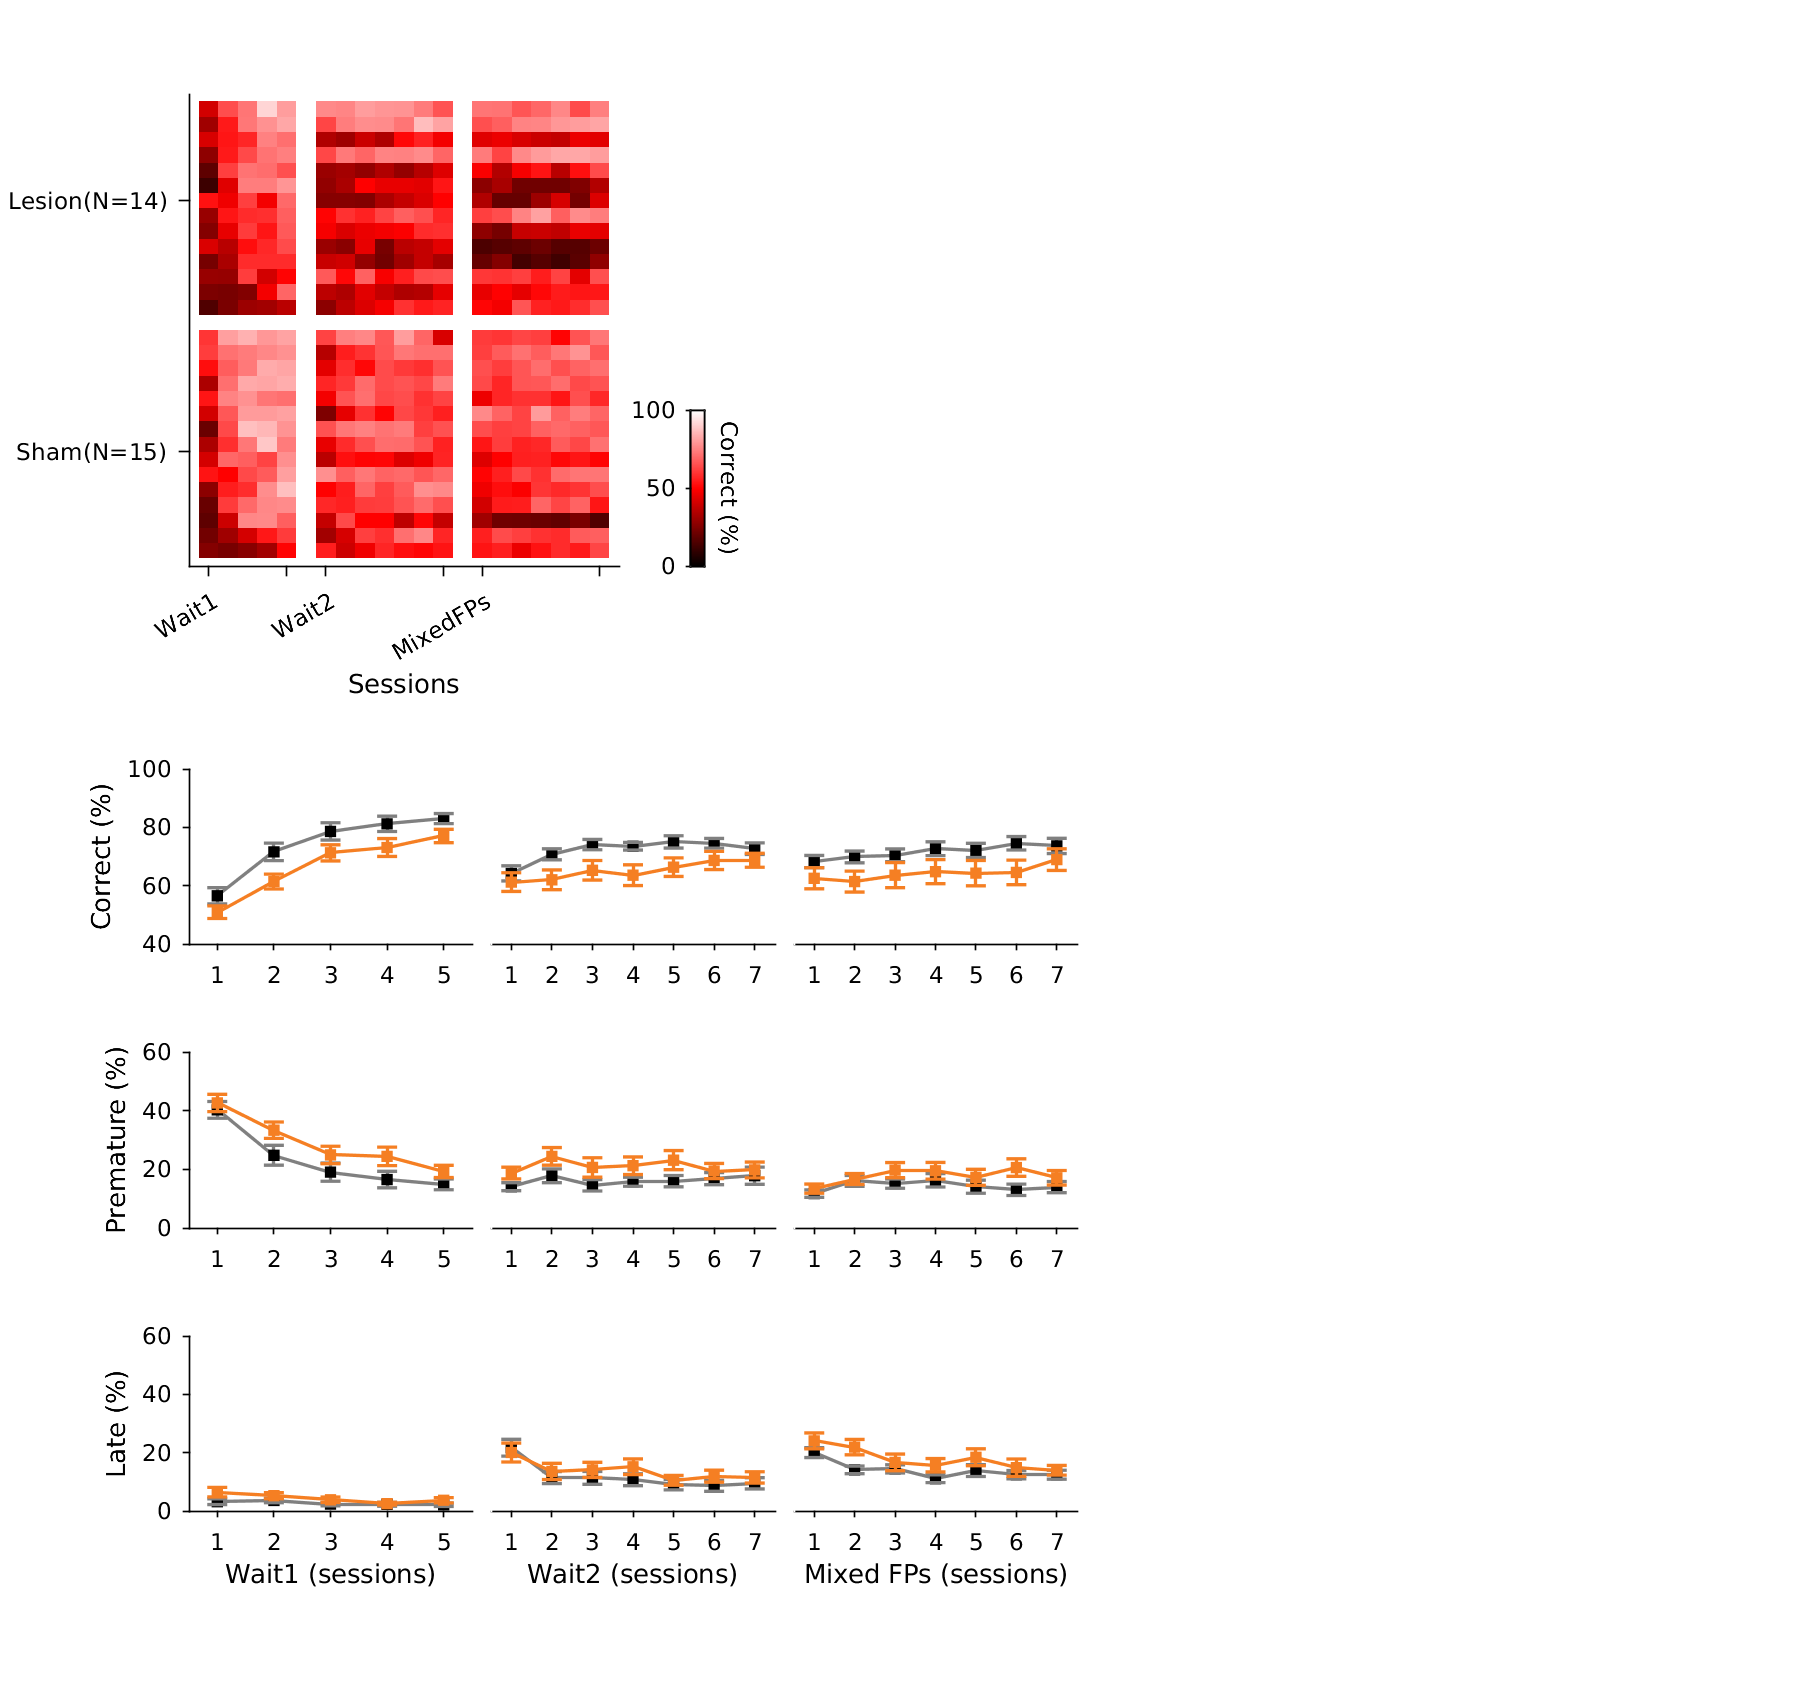

% Design a monte carlo simulation 
% We now have N_lesion and N_sham rats, with equal number of sessions in
% each task. 
% colors to pick from

cTab20 = [0.0901960784313726,0.466666666666667,0.701960784313725;0.682352941176471,0.780392156862745,0.901960784313726;0.960784313725490,0.498039215686275,0.137254901960784;0.988235294117647,0.729411764705882,0.470588235294118;0.152941176470588,0.631372549019608,0.278431372549020;0.611764705882353,0.811764705882353,0.533333333333333;0.843137254901961,0.149019607843137,0.172549019607843;0.964705882352941,0.588235294117647,0.592156862745098;0.564705882352941,0.403921568627451,0.674509803921569;0.768627450980392,0.690196078431373,0.827450980392157;0.549019607843137,0.337254901960784,0.290196078431373;0.768627450980392,0.607843137254902,0.576470588235294;0.847058823529412,0.474509803921569,0.698039215686275;0.956862745098039,0.709803921568628,0.807843137254902;0.501960784313726,0.501960784313726,0.501960784313726;0.780392156862745,0.780392156862745,0.776470588235294;0.737254901960784,0.745098039215686,0.196078431372549;0.854901960784314,0.862745098039216,0.549019607843137;0.113725490196078,0.737254901960784,0.803921568627451;0.627450980392157,0.843137254901961,0.890196078431373];
cRed = cTab20(7,:);
cRed2 = cTab20(8,:);
cGreen = cTab20(5,:);
cGreen2 = cTab20(6,:);
cBlue = cTab20(1,:);
cBlue2 = cTab20(2,:);
cGray = cTab20(15,:);
cGray2 = cTab20(16,:);
cOrange = cTab20(3,:);
cOrange2 = cTab20(4,:);
% plot sizes
xs          =       [2 5.2 8.4 16 16.5];
ys          =       [2 2 2];
% row 2
xs2         =       [2 7 8];
ys2         =       [5 6 6];
% row 3
xs3         =       [2 7 8];
ys3         =       [8 10 10];
% row 4
xs4         =       [2 7 8];
ys4         =       [12 10 10];

sizes       =       [3 3/1.618
                     NaN NaN
                     0.2 2];

colmapheight = 5;

% first, plot performance curves
set_matlab_default
hf = figure(24); clf(hf,'reset');
set(hf, 'name', 'Lesion effect', 'units', 'centimeters', 'position', [1 1 19 18],...
    'PaperPositionMode', 'auto','renderer','painter');  

ExpGroups       =       {'Sham', 'Lesion'};
GroupColors = {[0 0 0], cOrange};

% first plot, learning curve during Wait 1
ha1 = axes;
set(ha1, 'units', 'centimeters', 'position', [xs(1) ys3(1) sizes(1, :)],'xlim',[0.5 5.5], 'xtick', [1:5], 'ylim',[40 100], 'nextplot', 'add','tickDir', 'out',...
    'fontsize',7,'ticklength', [0.02 0.025]);
ylabel('Correct (%)')


thisTask        =       'Wait1';
GroupColors = {[0 0 0], cOrange};
PerScore = [];
PerScore.Wait1.Correct.Sham = [];
PerScore.Wait1.Correct.Lesion = []; 
PerScore.Wait1.Premature.Sham = [];
PerScore.Wait1.Premature.Lesion = [];
PerScore.Wait1.Late.Sham = [];
PerScore.Wait1.Late.Lesion = [];

for i = 1:length(UnqNames)

    IndThisGroup = find(strcmp(ExpGroups, UnqGroups(i)));
    CorrectScore = 100*SBS.Cor(strcmp(SBS.Subject, UnqNames(i)) & strcmp(SBS.Task, thisTask));
    PrematureScore = 100*SBS.Pre(strcmp(SBS.Subject, UnqNames(i)) & strcmp(SBS.Task, thisTask));
    LateScore = 100*SBS.Late(strcmp(SBS.Subject, UnqNames(i)) & strcmp(SBS.Task, thisTask));

%     plot([1: length(PerScore)], PerScore, 'color', GroupColors{IndThisGroup})

    switch IndThisGroup
        case 1
            PerScore.Wait1.Correct.Sham = [PerScore.Wait1.Correct.Sham CorrectScore];
            PerScore.Wait1.Premature.Sham = [PerScore.Wait1.Premature.Sham PrematureScore];
            PerScore.Wait1.Late.Sham = [PerScore.Wait1.Late.Sham LateScore];
        case 2
            PerScore.Wait1.Correct.Lesion = [PerScore.Wait1.Correct.Lesion CorrectScore];
            PerScore.Wait1.Premature.Lesion = [PerScore.Wait1.Premature.Lesion PrematureScore];
            PerScore.Wait1.Late.Lesion = [PerScore.Wait1.Late.Lesion LateScore];
    end;

end;

Nrats = size(PerScore.Wait1.Correct.Sham, 2)+size(PerScore.Wait1.Correct.Lesion, 2);

Wait1Sessions = [1:size(PerScore.Wait1.Correct.Sham, 1)]; 
mean_Sham = mean(PerScore.Wait1.Correct.Sham, 2);
sem_Sham  = std(PerScore.Wait1.Correct.Sham, 0, 2)/sqrt(size(PerScore.Wait1.Correct.Sham, 2));
mean_Lesion = mean(PerScore.Wait1.Correct.Lesion, 2);
sem_Lesion  = std(PerScore.Wait1.Correct.Lesion, 0, 2)/sqrt(size(PerScore.Wait1.Correct.Lesion, 2));

errorbar(Wait1Sessions, mean_Sham, sem_Sham, '-s', 'color', cGray,'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor','k', 'linewidth', 1)
errorbar(Wait1Sessions, mean_Lesion, sem_Lesion, '-s', 'color', cOrange,'MarkerSize',3,'MarkerEdgeColor',cOrange,'MarkerFaceColor',cOrange, 'linewidth', 1)
 
% Plot premature (Wait1)
ha1b = axes;
set(ha1b, 'units', 'centimeters', 'position', [xs(1) ys2(1) sizes(1, :)],'xlim',[0.5 5.5], 'xtick', [1:5], 'ylim',[0 60], 'nextplot', 'add','tickDir', 'out',...
    'fontsize',7,'ticklength', [0.02 0.025]);
ylabel('Premature (%)')

mean_Sham = mean(PerScore.Wait1.Premature.Sham, 2);
sem_Sham  = std(PerScore.Wait1.Premature.Sham, 0, 2)/sqrt(size(PerScore.Wait1.Premature.Sham, 2));
mean_Lesion = mean(PerScore.Wait1.Premature.Lesion, 2);
sem_Lesion  = std(PerScore.Wait1.Premature.Lesion, 0, 2)/sqrt(size(PerScore.Wait1.Premature.Lesion, 2));

errorbar(Wait1Sessions, mean_Sham, sem_Sham, '-s', 'color', cGray,'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor','k', 'linewidth', 1)
errorbar(Wait1Sessions, mean_Lesion, sem_Lesion, '-s', 'color', cOrange,'MarkerSize',3,'MarkerEdgeColor',cOrange, ...
    'MarkerFaceColor',cOrange, 'linewidth', 1)

% Plot late (Wait1)
ha1c = axes;
set(ha1c, 'units', 'centimeters', 'position', [xs(1) ys(1) sizes(1, :)],'xlim',[0.5 5.5], 'xtick', [1:5], 'ylim',[0 60], 'nextplot', 'add','tickDir', 'out',...
    'fontsize',7,'ticklength', [0.02 0.025]);
ylabel('Late (%)')
xlabel('Wait1 (sessions)')

mean_Sham = mean(PerScore.Wait1.Late.Sham, 2);
sem_Sham  = std(PerScore.Wait1.Late.Sham, 0, 2)/sqrt(size(PerScore.Wait1.Premature.Sham, 2));
mean_Lesion = mean(PerScore.Wait1.Late.Lesion, 2);
sem_Lesion  = std(PerScore.Wait1.Late.Lesion, 0, 2)/sqrt(size(PerScore.Wait1.Premature.Lesion, 2));

errorbar(Wait1Sessions, mean_Sham, sem_Sham, '-s', 'color', cGray,'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor','k', 'linewidth', 1)
errorbar(Wait1Sessions, mean_Lesion, sem_Lesion, '-s', 'color', cOrange,'MarkerSize',3,'MarkerEdgeColor',cOrange, ...
    'MarkerFaceColor',cOrange, 'linewidth', 1)

ha2 = axes;
colormapsize = [6*( length(Wait1Sessions) + 1)/Nrats colmapheight];

set(ha2, 'units', 'centimeters', 'position', [xs(1) ys4(1) colormapsize],'xlim',[0 6],'xtick', [1 5],'ylim',[0 size(PerScore.Wait1.Correct.Sham, 2)+size(PerScore.Wait1.Correct.Lesion, 2)+2], 'nextplot', 'add','tickDir', 'out',...
    'ytick', [size(PerScore.Wait1.Correct.Sham, 2)/2 size(PerScore.Wait1.Correct.Sham, 2)+2+size(PerScore.Wait1.Correct.Lesion, 2)/2], ...
    'yticklabel', {sprintf('%s(N=%2.0d)','Sham', size(PerScore.Wait1.Correct.Sham, 2)), sprintf('%s(N=%2.0d)','Lesion', size(PerScore.Wait1.Correct.Lesion, 2))},'fontsize',7,'ticklength', [0.02 0.025]);

xlabel('Sessions')
ylabel('Performance')
[~, sham_index] = sort(mean(PerScore.Wait1.Correct.Sham, 1));
[~, lesion_index] = sort(mean(PerScore.Wait1.Correct.Lesion, 1));
h_sham = imagesc([1:size(PerScore.Wait1.Correct.Sham, 1)], [1:size(PerScore.Wait1.Correct.Sham, 2)], PerScore.Wait1.Correct.Sham(:, sham_index)', [30 100]);
h_lesion = imagesc([1:size(PerScore.Wait1.Correct.Lesion, 1)], [1:size(PerScore.Wait1.Correct.Lesion, 2)]+size(PerScore.Wait1.Correct.Lesion, 2)+2, ...
    PerScore.Wait1.Correct.Lesion(:, lesion_index)', [30 100]);
mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
% hcbar = colorbar('location', 'EastOutSide','Units', 'Centimeters', 'Position', [xs(5) ys(1) sizes(3, :)]);
colormap(mycolormap);

% Second task type, Wait 2, 7 sessions 
ha3 = axes;
set(ha3, 'units', 'centimeters', 'position', [xs(2) ys3(1) sizes(1, :)],'xlim',[0.5 7.5], 'xtick', [1:7], 'ylim',[40 100], 'ytick', [], 'nextplot', 'add','tickDir', 'out',...
    'fontsize',7,'ticklength', [0.02 0.025], 'ycolor', 'w');

thisTask        =       'Wait2';

PerScore.Wait2.Correct.Sham = [];
PerScore.Wait2.Correct.Lesion = []; 
PerScore.Wait2.Premature.Sham = [];
PerScore.Wait2.Premature.Lesion = [];
PerScore.Wait2.Late.Sham = [];
PerScore.Wait2.Late.Lesion = [];

for i = 1:length(UnqNames)
    IndThisGroup = find(strcmp(ExpGroups, UnqGroups(i)));
    CorrectScore = 100*SBS.Cor(strcmp(SBS.Subject, UnqNames(i)) & strcmp(SBS.Task, thisTask));
    PrematureScore = 100*SBS.Pre(strcmp(SBS.Subject, UnqNames(i)) & strcmp(SBS.Task, thisTask));
    LateScore = 100*SBS.Late(strcmp(SBS.Subject, UnqNames(i)) & strcmp(SBS.Task, thisTask));
    switch IndThisGroup
        case 1
            PerScore.Wait2.Correct.Sham = [PerScore.Wait2.Correct.Sham CorrectScore];
            PerScore.Wait2.Premature.Sham = [PerScore.Wait2.Premature.Sham PrematureScore];
            PerScore.Wait2.Late.Sham = [PerScore.Wait2.Late.Sham LateScore];
        case 2
            PerScore.Wait2.Correct.Lesion = [PerScore.Wait2.Correct.Lesion CorrectScore];
            PerScore.Wait2.Premature.Lesion = [PerScore.Wait2.Premature.Lesion PrematureScore];
            PerScore.Wait2.Late.Lesion = [PerScore.Wait2.Late.Lesion LateScore];
    end;

end;


Wait2Sessions = [1:size(PerScore.Wait2.Correct.Sham, 1)]; 
mean_Sham = mean(PerScore.Wait2.Correct.Sham, 2);
sem_Sham  = std(PerScore.Wait2.Correct.Sham, 0, 2)/sqrt(size(PerScore.Wait2.Correct.Sham, 2));
mean_Lesion = mean(PerScore.Wait2.Correct.Lesion, 2);
sem_Lesion  = std(PerScore.Wait2.Correct.Lesion, 0, 2)/sqrt(size(PerScore.Wait2.Correct.Lesion, 2));
 
errorbar(Wait2Sessions, mean_Sham, sem_Sham, '-s', 'color', cGray,'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor','k', 'linewidth', 1);
errorbar(Wait2Sessions, mean_Lesion, sem_Lesion, '-s', 'color', cOrange,'MarkerSize',3,'MarkerEdgeColor',cOrange,'MarkerFaceColor',cOrange, 'linewidth', 1);

% Plot premature (Wait2)
ha2b = axes;
set(ha2b, 'units', 'centimeters', 'position', [xs(2) ys2(1) sizes(1, :)],'xlim',[0.5 7.5], 'xtick', [1:7], 'ylim',[0 60], 'ytick', [], 'nextplot', 'add','tickDir', 'out',...
    'fontsize',7,'ticklength', [0.02 0.025], 'ycolor', 'w');

mean_Sham = mean(PerScore.Wait2.Premature.Sham, 2);
sem_Sham  = std(PerScore.Wait2.Premature.Sham, 0, 2)/sqrt(size(PerScore.Wait2.Premature.Sham, 2));
mean_Lesion = mean(PerScore.Wait2.Premature.Lesion, 2);
sem_Lesion  = std(PerScore.Wait2.Premature.Lesion, 0, 2)/sqrt(size(PerScore.Wait2.Premature.Lesion, 2));

errorbar(Wait2Sessions, mean_Sham, sem_Sham, '-s', 'color', cGray,'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor','k', 'linewidth', 1)
errorbar(Wait2Sessions, mean_Lesion, sem_Lesion, '-s', 'color', cOrange,'MarkerSize',3,'MarkerEdgeColor',cOrange, ...
    'MarkerFaceColor',cOrange, 'linewidth', 1)

% Plot late (Wait2)
ha2c = axes;
set(ha2c, 'units', 'centimeters', 'position', [xs(2) ys(1) sizes(1, :)],'xlim',[0.5 7.5], 'xtick', [1:7], 'ylim',[0 60], 'ytick', [], 'nextplot', 'add','tickDir', 'out',...
    'fontsize',7,'ticklength', [0.02 0.025], 'ycolor', 'w');
xlabel('Wait2 (sessions)')

mean_Sham = mean(PerScore.Wait2.Late.Sham, 2);
sem_Sham  = std(PerScore.Wait2.Late.Sham, 0, 2)/sqrt(size(PerScore.Wait2.Premature.Sham, 2));
mean_Lesion = mean(PerScore.Wait2.Late.Lesion, 2);
sem_Lesion  = std(PerScore.Wait2.Late.Lesion, 0, 2)/sqrt(size(PerScore.Wait2.Premature.Lesion, 2));

errorbar(Wait2Sessions, mean_Sham, sem_Sham, '-s', 'color', cGray,'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor','k', 'linewidth', 1)
errorbar(Wait2Sessions, mean_Lesion, sem_Lesion, '-s', 'color', cOrange,'MarkerSize',3,'MarkerEdgeColor',cOrange, ...
    'MarkerFaceColor',cOrange, 'linewidth', 1)

h_sham2 = imagesc(ha2, [1:size(PerScore.Wait2.Correct.Sham, 1)]+size(PerScore.Wait1.Correct.Sham, 1)+1, [1:size(PerScore.Wait2.Correct.Sham, 2)], PerScore.Wait2.Correct.Sham(:, sham_index)', [30 100]);
h_lesion2 = imagesc(ha2, [1:size(PerScore.Wait2.Correct.Lesion, 1)]+size(PerScore.Wait1.Correct.Sham, 1)+1, [1:size(PerScore.Wait2.Correct.Lesion, 2)]+size(PerScore.Wait2.Correct.Lesion, 2)+2, ...
    PerScore.Wait2.Correct.Lesion(:, lesion_index)', [30 100]);
 
colormapsize = [6*(length(Wait2Sessions) + length(Wait1Sessions) + 2)/Nrats colmapheight];

set(ha2, 'units', 'centimeters', 'position', [xs(1) ys4(1) colormapsize],'xlim',[0 20],'xtick', [1 5],'nextplot', 'add','tickDir', 'out',...
   'fontsize',7,'ticklength', [0.02 0.025]);
 
% Third task type, 3FP, 7 sessions 
ha3  = axes;
set(ha3, 'units', 'centimeters', 'position', [xs(3) ys3(1) sizes(1, :)],'xlim',[0.5 7.5], 'xtick', [1:7], 'ylim',[40 100], 'ytick', [], 'nextplot', 'add','tickDir', 'out',...
    'fontsize',7,'ticklength', [0.02 0.025], 'ycolor', 'w');

thisTask        =       '3FPs';

PerScore.MixedFPs.Correct.Sham = [];
PerScore.MixedFPs.Correct.Lesion = []; 
PerScore.MixedFPs.Premature.Sham = [];
PerScore.MixedFPs.Premature.Lesion = [];
PerScore.MixedFPs.Late.Sham = [];
PerScore.MixedFPs.Late.Lesion = [];

for i = 1:length(UnqNames)
    IndThisGroup = find(strcmp(ExpGroups, UnqGroups(i)));
    CorrectScore = 100*SBS.Cor(strcmp(SBS.Subject, UnqNames(i)) & strcmp(SBS.Task, thisTask));
    PrematureScore = 100*SBS.Pre(strcmp(SBS.Subject, UnqNames(i)) & strcmp(SBS.Task, thisTask));
    LateScore = 100*SBS.Late(strcmp(SBS.Subject, UnqNames(i)) & strcmp(SBS.Task, thisTask));
    switch IndThisGroup
        case 1
            PerScore.MixedFPs.Correct.Sham = [PerScore.MixedFPs.Correct.Sham CorrectScore];
            PerScore.MixedFPs.Premature.Sham = [PerScore.MixedFPs.Premature.Sham PrematureScore];
            PerScore.MixedFPs.Late.Sham = [PerScore.MixedFPs.Late.Sham LateScore];
        case 2
            PerScore.MixedFPs.Correct.Lesion = [PerScore.MixedFPs.Correct.Lesion CorrectScore];
            PerScore.MixedFPs.Premature.Lesion = [PerScore.MixedFPs.Premature.Lesion PrematureScore];
            PerScore.MixedFPs.Late.Lesion = [PerScore.MixedFPs.Late.Lesion LateScore];
    end;
end;


MixedFPSessions = [1:size(PerScore.MixedFPs.Correct.Sham, 1)]; 
mean_Sham = mean(PerScore.MixedFPs.Correct.Sham, 2);
sem_Sham  = std(PerScore.MixedFPs.Correct.Sham, 0, 2)/sqrt(size(PerScore.MixedFPs.Correct.Sham, 2));

mean_Lesion = mean(PerScore.MixedFPs.Correct.Lesion, 2);
sem_Lesion  = std(PerScore.MixedFPs.Correct.Lesion, 0, 2)/sqrt(size(PerScore.MixedFPs.Correct.Lesion, 2));

errorbar(MixedFPSessions, mean_Sham, sem_Sham, '-s', 'color', cGray,'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor','k', 'linewidth', 1);
errorbar(MixedFPSessions, mean_Lesion, sem_Lesion, '-s', 'color', cOrange,'MarkerSize',3,'MarkerEdgeColor',cOrange,'MarkerFaceColor',cOrange, 'linewidth', 1);

h_sham3 = imagesc(ha2, [1:size(PerScore.MixedFPs.Correct.Sham, 1)]+size(PerScore.Wait1.Correct.Sham, 1)+2+size(PerScore.Wait2.Correct.Sham, 1), [1:size(PerScore.MixedFPs.Correct.Sham, 2)], PerScore.MixedFPs.Correct.Sham(:, sham_index)', [30 100]);
h_lesion3 = imagesc(ha2, [1:size(PerScore.MixedFPs.Correct.Lesion, 1)]+size(PerScore.Wait1.Correct.Sham, 1)+2+size(PerScore.Wait2.Correct.Sham, 1), [1:size(PerScore.MixedFPs.Correct.Lesion, 2)]+size(PerScore.MixedFPs.Correct.Lesion, 2)+2, ...
    PerScore.MixedFPs.Correct.Lesion(:,lesion_index)', [30 100]);
colormapsize = [6*(length(Wait2Sessions) + length(Wait1Sessions) + length(MixedFPSessions)+3)/Nrats colmapheight];

xticksessions(1) = 1;
xticksessions(2) = length(Wait1Sessions);
xticksessions(3) = length(Wait1Sessions)+1+1;
xticksessions(4) = length(Wait1Sessions)+1+length(Wait2Sessions);
xticksessions(5) = length(Wait1Sessions)+length(Wait2Sessions)+3;
xticksessions(6) = length(Wait1Sessions)+2+length(Wait2Sessions)+length(MixedFPSessions);

set(ha2, 'units', 'centimeters', 'position', [xs(1) ys4(1) colormapsize],'xlim',[0 length(Wait2Sessions) + length(Wait1Sessions) + length(MixedFPSessions)+3], ...
    'nextplot', 'add','tickDir', 'out',...
    'xtick', xticksessions, 'xticklabel', {'Wait1', '', 'Wait2', '','MixedFPs',''}, 'fontsize',7,'ticklength', [0.02 0.025]);
 
mycolormap = customcolormap([0 0.5 1], [1 1 1; 1 0 0; 0 0 0]);
hcbar = colorbar('location', 'EastOutSide','Units', 'Centimeters', 'Position', [xs(1)+colormapsize(1)+0.75 ys4(1) 0.15 colmapheight*0.33], ...
    'ytick', [0 50 100]/100,'TickDirection', 'out','ticklength', [0.02],'FontSize',7);
hcbar.TickLabels = num2cell(hcbar.Ticks*100);
barlabel = ylabel(hcbar,'Correct (%)','FontSize',7,'Rotation',270);
barlabel.Units = 'Centimeters';
barlabel.Position(1) = barlabel.Position(1)+1;


 % Plot premature (3FPs)
ha3b = axes;
set(ha3b, 'units', 'centimeters', 'position', [xs(3) ys2(1) sizes(1, :)],'xlim',[0.5 7.5], 'xtick', [1:7], 'ylim',[0 60], 'ytick', [], 'nextplot', 'add','tickDir', 'out',...
    'fontsize',7,'ticklength', [0.02 0.025], 'ycolor', 'w');

mean_Sham = mean(PerScore.MixedFPs.Premature.Sham, 2);
sem_Sham  = std(PerScore.MixedFPs.Premature.Sham, 0, 2)/sqrt(size(PerScore.MixedFPs.Premature.Sham, 2));
mean_Lesion = mean(PerScore.MixedFPs.Premature.Lesion, 2);
sem_Lesion  = std(PerScore.MixedFPs.Premature.Lesion, 0, 2)/sqrt(size(PerScore.MixedFPs.Premature.Lesion, 2));

errorbar(MixedFPSessions, mean_Sham, sem_Sham, '-s', 'color', cGray,'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor','k', 'linewidth', 1)
errorbar(MixedFPSessions, mean_Lesion, sem_Lesion, '-s', 'color', cOrange,'MarkerSize',3,'MarkerEdgeColor',cOrange, ...
    'MarkerFaceColor',cOrange, 'linewidth', 1)

% Plot late (3FPs)
ha2c = axes;
set(ha2c, 'units', 'centimeters', 'position', [xs(3) ys(1) sizes(1, :)],'xlim',[0.5 7.5], 'xtick', [1:7], 'ylim',[0 60], 'ytick', [], 'nextplot', 'add','tickDir', 'out',...
    'fontsize',7,'ticklength', [0.02 0.025], 'ycolor', 'w');
xlabel('Mixed FPs (sessions)')

mean_Sham = mean(PerScore.MixedFPs.Late.Sham, 2);
sem_Sham  = std(PerScore.MixedFPs.Late.Sham, 0, 2)/sqrt(size(PerScore.MixedFPs.Premature.Sham, 2));
mean_Lesion = mean(PerScore.MixedFPs.Late.Lesion, 2);
sem_Lesion  = std(PerScore.MixedFPs.Late.Lesion, 0, 2)/sqrt(size(PerScore.MixedFPs.Premature.Lesion, 2));

errorbar(MixedFPSessions, mean_Sham, sem_Sham, '-s', 'color', cGray,'MarkerSize',3,'MarkerEdgeColor','k','MarkerFaceColor','k', 'linewidth', 1)
errorbar(MixedFPSessions, mean_Lesion, sem_Lesion, '-s', 'color', cOrange,'MarkerSize',3,'MarkerEdgeColor',cOrange, ...
    'MarkerFaceColor',cOrange, 'linewidth', 1)


%% Save
tosavename = fullfile(pwd,'Figure','LesionBeforeLearning');
% saveas(hf,savename,'fig');
print(hf,'-dpng',tosavename);
print(hf,'-dpdf',tosavename,'-bestfit');
% print(hf,'-depsc2',savename);

exportgraphics(hf, [tosavename '.eps'],'ContentType','vector')